% 3.8 Adding MATLAB Components to Java Swing Containers 

% In Section 3.1.1, it has been mentioned that MATLAB objects such as axes 
%   (for plots or images) and uicontrols cannot be added to Swing containers,
%   since they do not have a javax.swing.JContainer wrapper. 

% It was advised to use these Java containers as long as their contained 
%   GUI is limited to Java components (JButtons, JComboBox, etc.). 
% This limitation is very annoying 
% — it would be most helpful to be able to place MATLAB axes or uicontrols 
%   within a JTabbedPane,a JSplitPane, or a pure-Java frame.

% Instead, we must rely on MATLAB-based workarounds 
%   (uitab and uisplitpane — see Section 4.3 and Chapter 10), 
%   which are cumbersome compared with their Java counterparts. 
% These were indeed the conventional wisdom and documented knowledge, until now.

% There actually is an undocumented, unsupported, and quite problematic method 
%   of placing MATLAB components in our Java GUI. 
% It is based on the fact that Swing components
%   (and all MATLAB GUI is ultimately that) 
%   can be reparented by being added to any Swing container: 
%   MATLAB uicontrols are easy to reparent, 
%   since they each have separate Swing component peers and associated container. 
% MATLAB axes cannot be separately reparented, 
%   since they do not have separate Swing component peers: 
%   as shall be explained in Chapter 7, all the figure's axes and plots 
%   are really graphic pixels drawn onto a single large java.awt.Canvas 
%   that spans the entire figure content area. 
% It is this Canvas (or one of its hierarchy ancestors, such as the ContentPane) 
%   which can be reparented onto any Java container. 

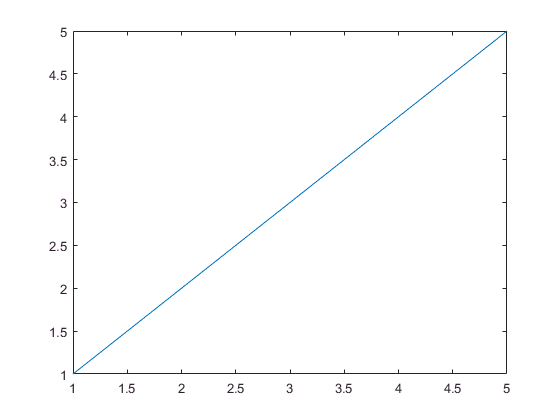

% Here is a simple example to move the Canvas onto a Java JFrame 
%   (we can move it onto any Swing container instead): 

% Display a simple plot within a MATLAB figure 
plot(1:5); 


% Get the MATLAB frame's plotting canvas container 
jFrame = get(handle(gcf),'JavaFrame');

jCanvas = jFrame.getAxisComponent;
jFrameProxy = jCanvas.getParent.getParent.getTopLevelAncestor;

% Prepare a new pure-Java frame
jf2 = javax.swing.JFrame;
jf2.pack;
jf2.setSize(jCanvas.getSize) ;
jf2.setTitle('My pure Java Frame');

% Add the MATLAB plot canvas to the new pure-Java frame 
awtinvoke(jf2,'add(Ljava.awt.Component;)',jCanvas); 
awtinvoke(jf2,'setVisible',1); % the plot shows in the Java Frame 

% Hide original MATLAB figure - only the Java frame remains visible 
set(gcf,'Visible','off'); 

% Update the MATLAB plot, actually modifying the axes in the JFrame 
plot(1:23) ; % plot in Java window is updated using regular HG MATLAB 
% awtinvoke(jf2,'show()'); % re-render (repaint) the plot
jf2.show;

% Note how we use jf2.show() in the last command above: 
%   For some unknown reason, repaint() and invalidate() are not enough 
%   to cause a plot re-rendering. 
% Also note that we use awtinvoke rather than direct invocation (jf2.show()),
%   because this operation needs to be done on the Java EDT thread. 
% Finally, note that the entire axes content of the MATLAB figure 
%   is transferred to the new container, not specific axes or uicontrols. 
% As far as Java is concerned, jCanvas is simply a single graphic image. 
% The main menu, toolbars, controls, and ActiveXes were not re-parented, 
%   since they belong to different containers in the MATLAB figure. 
% If we re-parent the root pane; these components are also moved 
%   to the new target container, along with the axes in jCanvas.
% Remember to set the target's size accordingly. 

% Re-parenting appears to work, sort of: 
%   when we close the original MATLAB figure, the Java frame window hangs, 
%   so remember to keep them both alive (or closed) together. 
% Many HG listeners are still connected to the original MATLAB figure, 
%   causing the figure to flicker when some HG actions are done. 
% For this reason, 
%   keeping the original MATLAB figure alive but hidden is advisable, 
%   and this has been done above using set(gcf'Visible','off'). 
% The downside is that when the figure is hidden, 
%   several interactive features (e.g., interactive zooming) are disabled. 

% We also need to handle other listeners (resizing, deletion, etc.) ourselves,
%   since the original component listeners remain 
%     attached to the original MATLAB figure,
%   and need to be re-attached to the new Java container.
% Such a re-parenting technique can be used to effectively remove the title bar 
%   from the figure window, 
%   by specifying jf2.setUndecorated(true) before jf2 is displayed.
% Also, see the discussion in Section 7.3.7. 

% The re-parenting process is deeply undocumented. 
% All in all, using re-parenting is extremely difficult to program correctly,
%   handling all edge cases.
% For this reason, I reiterate my earlier advice, 
%   to use MATLAB figures instead of Java frames; 
%   to use Java containers only for pure Java components 
%     and not for MATLAB components; 
%   and, in general, to add Java components to MATLAB figures 
%     rather than adding MATLAB components to Java frames. 

% In a related issue, adding Java components to a MATLAB-created frame, 
%   from within Java (as opposed to using javacomponent from within MATLAB), 
%   is also nontrivial and creates problems with repainting.

% An altogether different approach was suggested on CSSM: 
%   taking the screenshot of the Canvas and placing this as an image in Java.
% We would not be able to later modify this plot as in the re-parenting approach, 
%   but this approach does solve the system-hang issues. 

%% 3.9 Alternatives to Swing

% This chapter has focused on Swing and its extensive use in MATLAB. 
% However, Swing is by no means the only Java-based GUI framework 
%   available for MATLAB programmers. 
% Alternative UI toolkits can be used, such as 
%   the popular SWT, the older AWT, or the lesser-known Qt.
% MATLAB uses Swing internally, 
%   so it is natural to continue developing using Swing, 
%   for a consistent look and feel, 
%   enabling use of internal MATLAB components and other side benefits. 
% AWT is Swing's predecessor and much outdated, 
%   so there is no real reason to use it except for very specific tasks: 
%   Interested readers can, however, try to use SWT or Qt, 
%   which sometimes provide benefits that Swing lacks.
% Some open-source projects attempt to merge Swing and SWT, 
%   thus providing the benefits of both. 


% Here is a simple "Hello World!" MATLAB-SWT application:

import org.eclipse.swt.*; 
import org.eclipse.swt.widgets.*; 
import org.eclipse.swt.graphics.*; 
import org.eclipse.swt.layout.*; 
display = Display;

Undefined function or variable 'Display'.

shell = Shell(display) ; 
shell.setLayout(GridLayout); 
label=Label(shell, SWT.NONE); 
label.setText('Hello, World!'); 
button=Button(shell, SWT.PUSH); 
button.setText('Click me ! ') ; 
shell.pack; 
label.pack 
shell.open 
% Wait for the window to be closed, then dispose (cleanup) components 
while (~shell.isDisposed) 
if (display.readAndDispatch) 
display.sleep; 
end 
end 
display.dispose; 
label.dispose; 
button.dispose; 

% Note that mixing components (widgets) of different toolkits
%   on the same figure window may cause unexpected behavior.
% For example, when AWT and Swing components were mixed in JVM versions 
%   prior to 1.6 update 12, 
%   the AWT components always overlapped the Swing widgets, 
%   regardless of component priority. 
% Therefore, because MATLAB uses Swing, 
%   if we plan to integrate non-Swing toolkits, 
%   we should expect such problems and carefully test our application. 

